% Load EEGLAB
eeglab;

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.3 to the path
EEGLAB: adding "Fileio" v20240111 to the path
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "SIFT" v1.6 to the path
EEGLAB: adding "bva-io" v1.73 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
EEGLAB: adding "get_entropy" v1.0 (see >> help eegplugin_entropy)
EEGLAB: adding "neuroscanio" v1.8 (see >> help eegplugin_neuroscanio)


You are using the latest version of EEGLAB.



% Path to the folder containing .set files
data_folder = '/MATLAB Drive/Data and Code/Dataset/FilipeDatasetv2';

% Parameters for get_entropy function
entropyType = 'Sample entropy'; % Set the entropy type
tau = 2; % Time lag
m = 3; % Embedding dimension
vis = 1; % Yes, visualize outputs

setFiles = dir(fullfile(data_folder, '*.set'));

% Suppress warnings
warning('off', 'all');

% Loop through each .set file
for k = 1:length(setFiles)
    % Define the expected CSV filename
    csv_filename = fullfile(data_folder, [setFiles(k).name(1:end-4), '_entropy_values.csv']);
    
    % Check if the CSV file already exists
    if exist(csv_filename, 'file')
        fprintf('CSV file already exists for %s. Skipping...\n', setFiles(k).name);
        continue;
    end
    
    try
        % Load the selected EEG file
        EEG = pop_loadset('filename', setFiles(k).name, 'filepath', data_folder);
        fprintf('File loaded: %s\n', fullfile(data_folder, setFiles(k).name));
        
        % Select all channels and convert to cell array of character vectors
        chanlist = {EEG.chanlocs.labels};
        
        % Compute sample entropy
        fprintf('Computing entropy...\n');
        EEG = get_entropy(EEG, entropyType, chanlist, tau, m, [], [], [], [], vis);
        fprintf('Entropy computation complete.\n');
        
        % Check if entropy fields exist
        if isfield(EEG, 'entropy')
            fprintf('EEG.entropy fields exist for %s.\n', setFiles(k).name);
        else
            error('EEG.entropy field is missing for %s.', setFiles(k).name);
        end
        
        % Verify entropy values are computed
        entropyValues = EEG.entropy;
        if isempty(entropyValues)
            error('Entropy values are empty.');
        end
        
        % Prepare to save entropy values to a CSV file
        fprintf('Saving CSV to: %s\n', csv_filename);
        
        try
            fileID = fopen(csv_filename, 'w');
            if fileID == -1
                error('Cannot open file for writing: %s', csv_filename);
            end
            
            fprintf(fileID, 'Channel;Entropy\n');
            for ch = 1:length(entropyValues)
                entropy_str = strrep(num2str(entropyValues(ch), '%.15f'), '.', ',');
                fprintf(fileID, '%s;%s\n', chanlist{ch}, entropy_str);
            end
            fclose(fileID);
            fprintf('Entropy values saved to %s\n', csv_filename);
        catch fileError
            fprintf('Error writing CSV file: %s\n', fileError.message);
        end
        
        % Print a message to indicate the file is processed
        fprintf('Processed: %s\n', setFiles(k).name);
    catch ME
        % Print the warning message
        fprintf('Warning: %s\n', ME.message);
    end
end

CSV file already exists for PD804_off_segment1.set. Skipping...
CSV file already exists for PD804_off_segment2.set. Skipping...
CSV file already exists for PD804_off_segment3.set. Skipping...
CSV file already exists for PD804_off_segment4.set. Skipping...
CSV file already exists for PD804_on_segment1.set. Skipping...
CSV file already exists for PD804_on_segment2.set. Skipping...
CSV file already exists for PD804_on_segment3.set. Skipping...
CSV file already exists for PD804_on_segment4.set. Skipping...
CSV file already exists for PD805_off_segment1.set. Skipping...
CSV file already exists for PD805_off_segment2.set. Skipping...
CSV file already exists for PD805_off_segment3.set. Skipping...
CSV file already exists for PD805_off_segment4.set. Skipping...
CSV file already exists for PD805_on_segment1.set. Skipping...
CSV file already exists for PD805_on_segment2.set. Skipping...
CSV file already exists for PD805_on_segment3.set. Skipping...
CSV file already exists for PD805_on_segment4.s

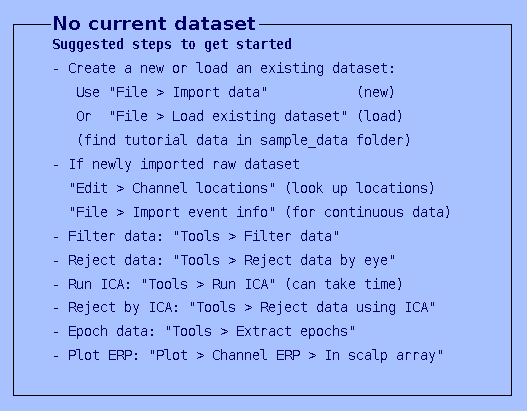


% Re-enable warnings
warning('on', 'all');

% Update EEGLAB GUI
eeglab redraw;